# 5주차 과제 — 안정도와 정상상태 오차

**제어시스템설계** · 충남대학교 자율운항시스템공학과

문제는 **세 개**입니다.

- **1. 몸풀기** (쉬움 · 수업 중 10분 · 30점) — 임계이득 손으로 구하기

- **2. 기본** (중간 · 40분 · 70점) — 시스템 타입과 오차 구하기

- **3. 도전** (선택 · 가산점 10점) — 오차를 없애면 무엇을 잃는가

**3번은 선택입니다.** 1번과 2번만 해도 만점입니다.

clc; close all;
s = tf('s');

## 1. 몸풀기 — 얼마까지 이득을 키울 수 있나

**강의노트 2-3절을 그대로 보면 됩니다.**

오늘의 구조입니다.

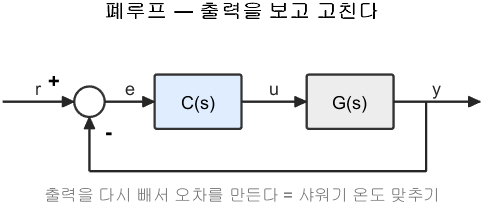

폐루프 — 출력을 보고 고친다

**그림 파일** `loop_closed.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_closed')`

## 1-1. 손으로 먼저

플랜트는 이것입니다.


$$G(s) = \frac{1}{s(s+1)(s+5)}$$


비례이득 $K$ 로 루프를 닫으면 특성방정식은 이렇게 됩니다.


$$s(s+1)(s+5) + K = s^3 + 6s^2 + 5s + K = 0$$


3차 다항식 $a_3 s^3 + a_2 s^2 + a_1 s + a_0$ 의 안정 조건은 두 줄입니다.

- 계수가 전부 양수여야 한다

- $a_2\,a_1 > a_3\,a_0$

할 일 — 위 조건에 값을 넣어 **임계이득**을 손으로 구하십시오.


$$6 \times 5 > 1 \times K \qquad \Rightarrow \qquad K < \;?$$


## 1-2. 숫자로 확인

`TODO` 한 줄만 채우십시오.

쓸 명령

- `roots(den)` — 다항식의 근. 하나라도 실수부가 $0$ 보다 크면 불안정

G1 = 1/(s*(s+1)*(s+5));

fprintf('\n     K     극점 중 가장 오른쪽 실수부   판정\n');
fprintf('  ------  --------------------------  --------\n');
for K = [10 20 29 30 31 40]
    den = [1 6 5 K];
    mx  = NaN;    % TODO : max(real(roots(den))) 을 계산하십시오
    if isnan(mx)
        fprintf('  %6.1f  (아직 안 채움)\n', K);
    else
        if mx < 0, v = '안정'; else, v = '불안정'; end
        fprintf('  %6.1f  %26.4f  %s\n', K, mx, v);
    end
end

## 1-3. 그림으로 보기

코드는 다 되어 있습니다. 이득을 키우면 극점이 어디로 가는지 봅니다.

Ks = linspace(0.5, 45, 200);
figure; hold on; grid on;
for K = Ks
    r = roots([1 6 5 K]);
    plot(real(r), imag(r), '.', 'Color', [0.3 0.5 0.8], 'MarkerSize', 6);
end
r30 = roots([1 6 5 30]);
plot(real(r30), imag(r30), 'rx', 'MarkerSize', 14, 'LineWidth', 2);
xline(0, 'k-', 'LineWidth', 1.5);
xlabel('실수부'); ylabel('허수부');
title('이득을 키우면 극점이 오른쪽으로 넘어간다 (빨간 x = 임계)');

## 1-4. 답할 것 (두 문장이면 됩니다)

- 손으로 구한 임계이득과 표의 결과가 맞는가?

- 극점이 허수축을 넘는 순간 응답은 어떻게 되겠는가?

## 2. 기본 — 시스템 타입과 정상상태 오차

**강의노트 4절부터 6절까지를 그대로 보면 됩니다.**

**시스템 타입**이란 개루프 $L(s)$ 에 들어 있는 **적분기(**$1/s$**)의 개수** 입니다.

- 타입 0 : 적분기 없음

- 타입 1 : 적분기 하나

- 타입 2 : 적분기 둘

그리고 규칙은 이것 하나입니다.

- **적분기 하나가 입력 한 단계를 감당한다**

- 계단은 1 단계, 램프는 2 단계, 포물선은 3 단계

- 감당하면 오차 $0$, 딱 맞으면 유한한 오차, 모자라면 오차 $\infty$

## 2-1. 세 시스템의 타입 판정

아래 세 개루프의 타입을 **눈으로** 판정하십시오. 계산이 필요 없습니다.


$$L_a(s) = \frac{5}{(s+1)(s+5)}, \qquad L_b(s) = \frac{5}{s(s+5)}, \qquad L_c(s) = \frac{5(s+1)}{s^2(s+5)}$$


분모에 $s$ 가 몇 개 있는지만 세면 됩니다.

La = 5/((s+1)*(s+5));
Lb = 5/(s*(s+5));
Lc = 5*(s+1)/(s^2*(s+5));

## 2-2. 오차상수 구하기

오차상수의 정의는 이렇습니다.


$$K_p = \lim_{s\to 0} L(s), \qquad K_v = \lim_{s\to 0} sL(s), \qquad K_a = \lim_{s\to 0} s^2 L(s)$$


MATLAB 에서는 `dcgain` 으로 극한을 구할 수 있습니다.

- $K_p$ 는 `dcgain(L)`

- $K_v$ 는 `dcgain(s*L)`

- $K_a$ 는 `dcgain(s^2*L)`

`TODO` 세 줄을 채우십시오.

fprintf('\n  시스템   타입   Kp        Kv        Ka\n');
fprintf('  ------  ----  --------  --------  --------\n');
Ls = {'La', La; 'Lb', Lb; 'Lc', Lc};
for i = 1:3
    L = Ls{i,2};
    ty = sum(abs(pole(L)) < 1e-9);          % 원점 극점의 개수 = 타입
    Kp_ = NaN;    % TODO : dcgain(L)
    Kv_ = NaN;    % TODO : dcgain(s*L)
    Ka_ = NaN;    % TODO : dcgain(s^2*L)
    fprintf('  %-6s  %4d  %8.3f  %8.3f  %8.3f\n', Ls{i,1}, ty, Kp_, Kv_, Ka_);
end

## 2-3. 계단 오차를 예측하고 확인하기

계단 입력에 대한 정상상태 오차는 이렇습니다.


$$e_{ss} = \frac{1}{1 + K_p}$$


타입 1 이상이면 $K_p = \infty$ 이므로 오차가 $0$ 입니다.

아래 코드는 예측값과 실제 응답을 비교합니다. 실행만 하면 됩니다.

t2 = (0:0.02:20)';
figure; hold on; grid on;
fprintf('\n  시스템   예측 오차   실측 오차\n');
fprintf('  ------  ---------  ---------\n');
for i = 1:3
    L = Ls{i,2};
    T = feedback(L, 1);
    y = step(T, t2);
    ess_pred = 1/(1 + dcgain(L));
    fprintf('  %-6s  %9.4f  %9.4f\n', Ls{i,1}, ess_pred, 1 - y(end));
    plot(t2, y, 'LineWidth', 2, 'DisplayName', Ls{i,1});
end
yline(1, 'k--', 'HandleVisibility','off');
xlabel('시간 [s]'); ylabel('출력');
legend('Location','southeast');
title('타입이 높을수록 계단 오차가 사라진다');

## 2-4. 답할 것 (세 문장이면 됩니다)

- 세 시스템의 타입은 각각 얼마인가?

- 계단 입력에서 오차가 남는 것은 어느 것인가? 왜인가?

- $L_b$ 에 **램프 입력**을 넣으면 오차가 $0$ 이 되겠는가? (계산하지 말고 위 규칙만으로 답하십시오)

## 3. 도전 (선택) — 오차를 없애면 무엇을 잃는가

**이 문제는 선택입니다. 안 해도 만점입니다.** 가산점 10점입니다.

1번의 플랜트에 적분기를 하나 붙여 타입을 올려 봅니다.


$$G(s) = \frac{1}{s(s+1)(s+5)} \qquad \rightarrow \qquad C(s)G(s) = \frac{K}{s} \cdot \frac{1}{s(s+1)(s+5)}$$


할 일

- 새 특성방정식을 쓰고 **4차** 가 되는 것을 확인하라

- $K$ 를 훑어 가며 `roots` 로 안정 한계를 구하라

- 1번에서 구한 한계($K < 30$)와 비교하라

답할 것 (한 문장)

- 적분기를 넣어 오차를 없앤 대신 무엇을 잃었는가?

이것이 5주차의 가장 중요한 교훈입니다. **오차를 없애는 일과 안정하게 만드는 일은 서로 반대 방향으로 당깁니다.**

TODO : 여기에 코드를 작성하십시오

## 채점 기준

- **1. 몸풀기** 30점 — 손 계산과 표, 두 질문에 답했는가

- **2. 기본** 70점 — 타입 판정, 오차상수, 세 질문에 답했는가

- **3. 도전** 가산점 10점

감점 사항 (세 가지뿐입니다)

- 축 이름이나 범례가 없는 그림

- 손 계산 없이 답만 적은 경우

- 코드가 오류로 멈추는 경우